clear;
clc
Parameters
s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



A = [0        0              1               0;
     0        0              0               1;
     0      g*mp/mc       -d1/mc         -d2/(L*mc);
     0 g*(mc+mp)/(L*mc) -d1/(L*mc) d2*(mc+mp)/(L*L*mc*mp)]

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    3.2733   -0.0067   -0.0067
         0   13.0933   -0.0067    0.0267


B = [0;0;1/mc;1/(L*mc)]

B =          0
         0
    0.6667
    0.6667


C = [0 1 0 0]

C =      0     1     0     0


D = 0

D = 0

SYS = ss(A,B,C,D)

SYS =
 
  A = 
              x1
   x1          0
   x2          0
   x3          0
   x4          0
 
              x2
   x1          0
   x2          0
   x3      3.273
   x4      13.09
 
              x3
   x1          1
   x2          0
   x3  -0.006667
   x4  -0.006667
 
              x4
   x1          0
   x2          1
   x3  -0.006667
   x4    0.02667
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.6667
   x4  0.6667
 
  C = 
       x1
   y1   0
 
       x2
   y1   1
 
       x3
   y1   0
 
       x4
   y1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



p = pole(SYS)

p =     3.6310
   -3.6060
   -0.0050
         0


[z,g] = zero(SYS)

z = 	1.0e+-18 *

   -0.4337
         0


g = 0.6667

pzmap(SYS)
Tfq2 = tf(SYS)

Tfq2 =
 


ZPK = zpk(z,p,g)

## Task 2

A =          0         0    1.0000         0
         0         0         0    1.0000
         0    3.2733   -0.0067   -0.0067
         0   13.0933   -0.0067    0.0267


B =          0
         0
    0.6667
    0.6667


C =      0     1     0     0


D = 0

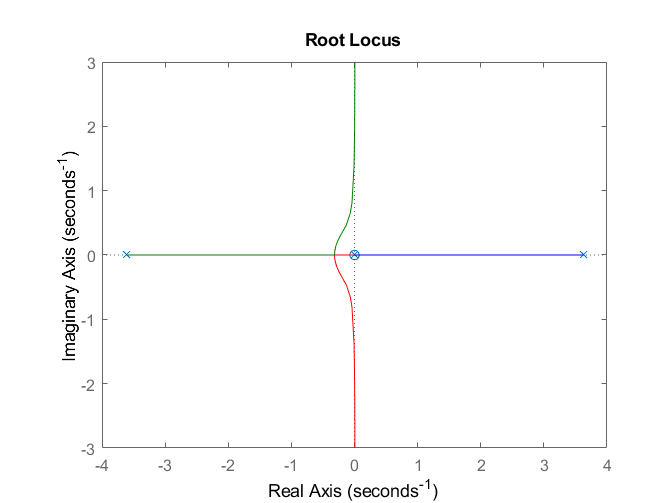


save SYS

%%The root locus remains the same if we use P-controller. So, even after using P-controller we are going to have roots on the right half of the plane which makes the system unstable

%sisotool(Tfq2)

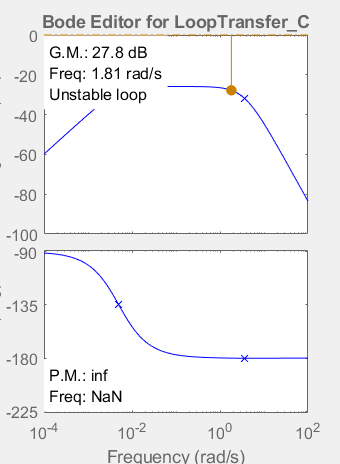

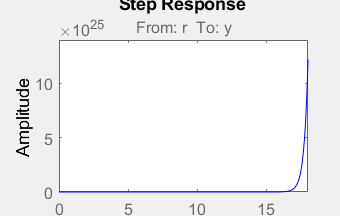

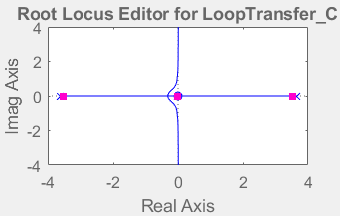

%co